%%
%% cubic.m
%%
%% M-file to compute a cubic polynomial reference trajectory
%%
%% q0 = initial position
%% v0 = initial velocity
%% q1 = final position
%% v1 = final velocity
%% t0 = initial time
%% tf = final time
%%
clear
% d = input(\ initial data = [q0,v0,q1,v1,t0,tf] = )
q0 = 300; v0 = 20; q1 = 550; v1 = 0;
t0 = 0; tf = 4.4305;
t = linspace(t0,tf,100*(tf-t0));
c = ones(size(t));
M = [   1 t0 t0^2 t0^3   ;
        0 1  2*t0 3*t0^2 ;
        1 tf tf^2 tf^3   ;
        0 1  2*tf 3*tf^2 ];
%%
b = [q0; v0; q1; v1];
a = inv(M)*b
%%
% qd = reference position trajectory
% vd = reference velocity trajectory
% ad = reference acceleration trajectory
%
qd = a(1).*c + a(2).*t +a(3).*t.^2 + a(4).*t.^3;
vd = a(2).*c +2*a(3).*t +3*a(4).*t.^2;
ad = 2*a(3).*c + 6*a(4).*t
plot(t,qd)
plot(t,vd)

%light_cubic_traj
d0 = 0;
d1 = 10;

v_set = 30;

ds = d1-d0;
T = ds/(v_set / 1.5);
t = linspace(0,T,1000*(T));

co0 = d0;
co2 = (3*T*ds)/T^3;
co3 = (-2*ds)/T^3;

qd = co0 + (co2.*t.^2) + (co3.*t.^3)

qd =          0    0.0001    0.0005    0.0011    0.0019    0.0030    0.0043    0.0058    0.0076    0.0096    0.0119    0.0144    0.0171    0.0200    0.0232    0.0266    0.0302    0.0340    0.0381    0.0424    0.0469    0.0516    0.0566    0.0618    0.0672    0.0728    0.0786    0.0847    0.0909    0.0974    0.1041    0.1110    0.1181    0.1254    0.1330    0.1407    0.1486    0.1568    0.1651    0.1737    0.1825    0.1914    0.2006    0.2100    0.2195    0.2293    0.2393    0.2494    0.2598    0.2703


qv = (2*co2.*t)+ (3*co3.*t.^2)

qv =          0    0.2400    0.4790    0.7171    0.9542    1.1904    1.4255    1.6598    1.8930    2.1253    2.3566    2.5870    2.8164    3.0448    3.2723    3.4988    3.7243    3.9489    4.1725    4.3952    4.6168    4.8376    5.0573    5.2761    5.4940    5.7108    5.9267    6.1417    6.3556    6.5686    6.7807    6.9918    7.2019    7.4111    7.6192    7.8265    8.0327    8.2380    8.4424    8.6457    8.8482    9.0496    9.2501    9.4496    9.6482    9.8457   10.0424   10.2380   10.4327   10.6265


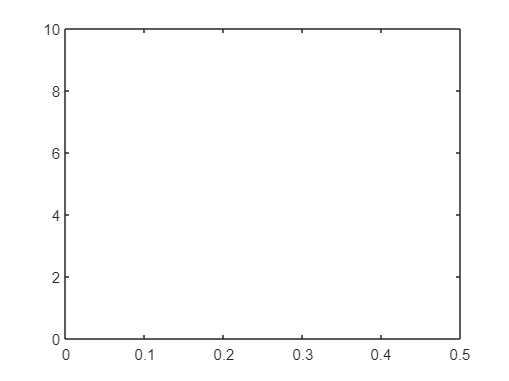

plot(t,qd)

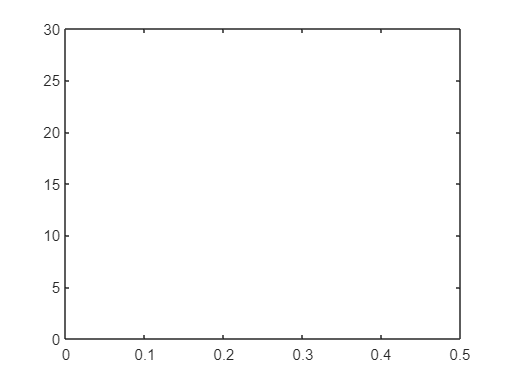

plot(t,qv)

d0 = 300;
d1 = 550;
v0 = 20;
t0 = 0;
t1 = 24.4157;


ds = d1-d0;
t = linspace(t0,t1,1000*(t1));
T = t1;

co0 = d0;
co1 = v0;
co2 = -((3*d0 - 3*d1 + 2*t1*v0)/t1^2); 
co3 = (2*d0 - 2*d1 + t1*v0)/t1^3;

qd = co0 + (co1.*t) + (co2.*t.^2) + (co3.*t.^3)
qv = co1 + (2*co2.*t)+ (3*co3.*t.^2)
plot(t,qd)
plot(t,qv)

clear all
syms t0 tf q0 qf vf T real
syms v0 V_maxin real
t0=0;
M=[1 t0 t0^2 t0^3;0 1 2*t0 3*t0^2;1 tf tf^2 tf^3 ;0 1 2*tf 3*tf^2]
abar = simplify(inv(M)*[q0;v0;qf;0])

c2 = abar(3);
c3 = abar(4);
eqn = (2*c2)+(6*c3*T) == 0
T_max = solve(eqn,T)
% T_max = abs(T_max)
% V_max = v0+(2*c2*T_max)+(3*c3*((T_max)^2))
eq = v0+(2*c2*T_max)+(3*c3*((T_max)^2))-V_maxin == 0
% Tf_for_Vmax = solve(V_max == V_max_in,tf,'Real',true)
Tf_for_Vmax = solve(eq,tf,'Real', true)

subs(Tf_for_Vmax(1),[q0,qf,V_maxin,v0],[300,550,80,20])

Cubic Trajectory V0 != 0

q0 = 300; v0 = 20; q1 = 550; v1 = 0;
t0 = 0; V_maxin = 80;
tf = -(3*(V_maxin*q0 - V_maxin*q1 + q0*v0 - q1*v0 + sqrt(V_maxin*(V_maxin - v0)*(q0 - q1)^2)))/(v0^2 + 3*V_maxin*v0);
t = linspace(t0,tf,100*(tf-t0));
c = ones(size(t));
M = [   1 t0 t0^2 t0^3   ;
        0 1  2*t0 3*t0^2 ;
        1 tf tf^2 tf^3   ;
        0 1  2*tf 3*tf^2 ];
%%
b = [q0; v0; q1; v1];
a = inv(M)*b

a =   300.0000
   20.0000
   29.1802
   -4.7305


%%
% qd = reference position trajectory
% vd = reference velocity trajectory
% ad = reference acceleration trajectory
%
qd = a(1).*c + a(2).*t +a(3).*t.^2 + a(4).*t.^3;
vd = a(2).*c +2*a(3).*t +3*a(4).*t.^2;
ad = 2*a(3).*c + 6*a(4).*t

ad =    58.3603   58.0758   57.7913   57.5068   57.2223   56.9378   56.6533   56.3688   56.0843   55.7998   55.5153   55.2308   54.9463   54.6618   54.3773   54.0928   53.8083   53.5238   53.2393   52.9548   52.6703   52.3858   52.1013   51.8168   51.5323   51.2478   50.9633   50.6788   50.3943   50.1098   49.8253   49.5408   49.2563   48.9718   48.6873   48.4028   48.1183   47.8338   47.5493   47.2648   46.9803   46.6958   46.4113   46.1268   45.8423   45.5578   45.2733   44.9888   44.7043   44.4198


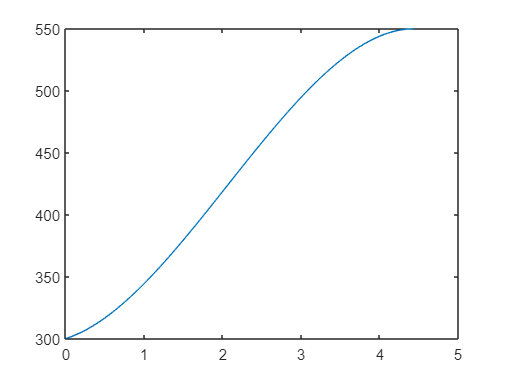

plot(t,qd)

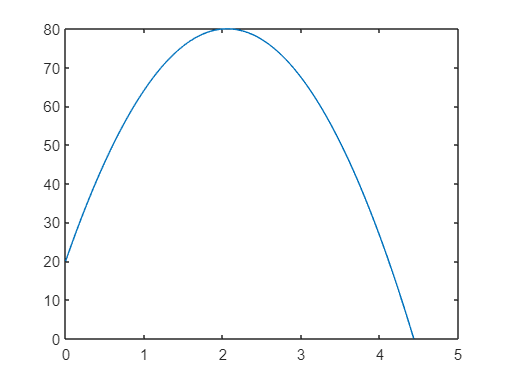

plot(t,vd)

d0 = 0;
d1 = 400;
v0 = 5;
t0 = 0;
t1 = 15;


ds = d1-d0;
t = linspace(t0,t1,1000*(t1));
T = t1;

co0 = d0;
co1 = v0;
co2 = -((3*d0 - 3*d1 + 2*t1*v0)/t1^2); 
co3 = (2*d0 - 2*d1 + t1*v0)/t1^3;

qd = co0 + (co1.*t) + (co2.*t.^2) + (co3.*t.^3)
qv = co1 + (2*co2.*t)+ (3*co3.*t.^2)
plot(t,qd)
plot(t,qv)

clear all
syms t0 tf q0 qf v0 vf real
t0 = 0;
M = [   1 t0 t0^2 t0^3   ;
        0 1  2*t0 3*t0^2 ;
        1 tf tf^2 tf^3   ;
        0 1  2*tf 3*tf^2 ];

abar = simplify(inv(M)*[q0;v0;0;qf]) %%[q0;v0;a0;qf;vf;af]


clear all
syms t0 tf q0 qf v0 vf real
t0 = 0;
M = [ 1 t0 t0^2 t0^3 t0^4 t0^5;
0 1 2*t0 3*t0^2 4*t0^3 5*t0^4;
0 0 2 6*t0 12*t0^2 20*t0^3;
1 tf tf^2 tf^3 tf^4 tf^5;
0 1 2*tf 3*tf^2 4*tf^3 5*tf^4;
0 0 2 6*tf 12*tf^2 20*tf^3];

abar = simplify(inv(M)*[q0;v0;0;qf;0;0]) %%[q0;v0;a0;qf;vf;af]

q0 = 0;

qf = 400;
v0 = 40;
t0 = 0;
% tf = 15;

dq = qf - q0;
tf = abs(dq/(50/1.5))

t = linspace(t0,tf,1000*(tf - t0));
T = tf;

ds = q0 - qf;
tfv0 = tf*v0;

co0 = q0;
co1 = v0;
co2 = 0; 
co3 =  - (2*(5*ds + 3*tfv0))/tf^3;
co4 = (15*ds + 8*tfv0)/tf^4;
co5 =  - (3*(2*ds + tfv0))/tf^5;

% qd = co0 + (co1.*t) + (co2.*t.^2) + (co3.*t.^3) + (co4.*t.^4) + (co5.*t.^5)
% qv = co1 + (2*co2.*t)+ (3*co3.*t.^2) + (4*co4.*t.^3) + (5*co5.*t.^4)
qd = co0 + (co1.*t) + (co3.*t.^3) + (co4.*t.^4) + (co5.*t.^5)
qv = co1 + (3*co3.*t.^2) + (4*co4.*t.^3) + (5*co5.*t.^4)
qa = (6*co3.*t) + (12*co4.*t.^2) + (20*co5.*t.^3)
plot(t,qd)
plot(t,qv)
plot(t,qa)